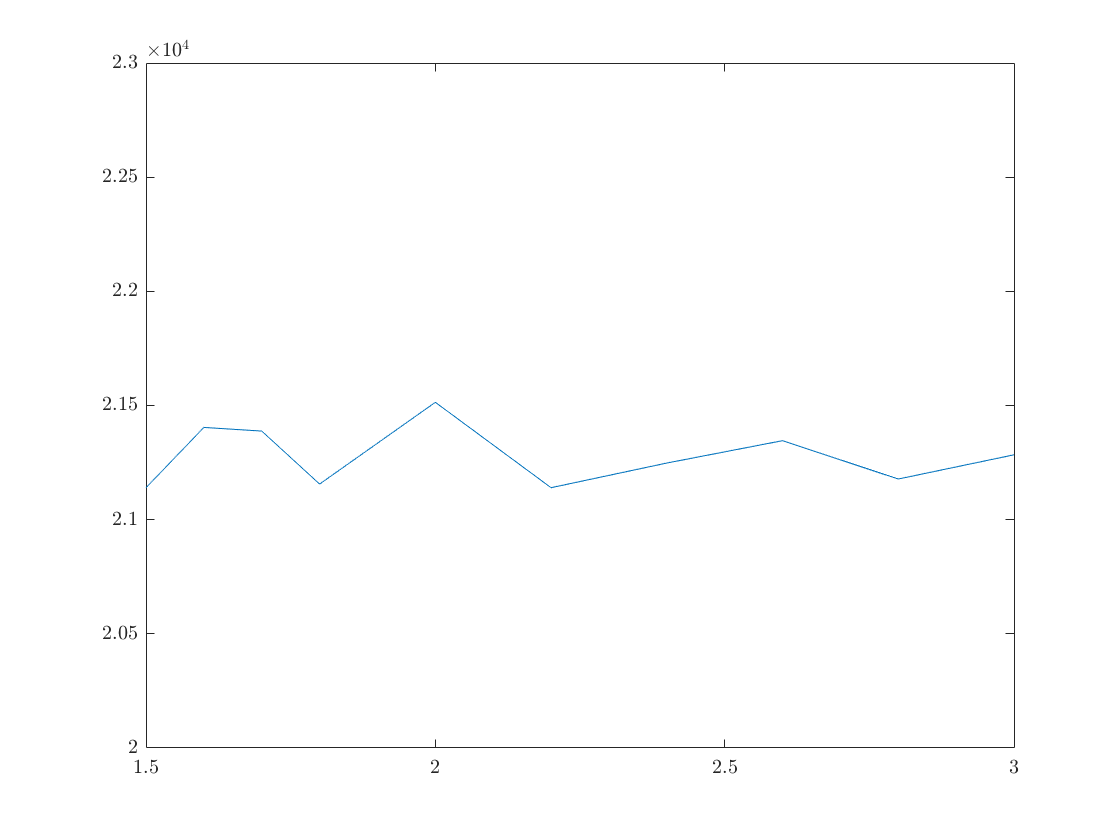

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 12 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, title, legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

Ma = [1.5,1.6,1.7,1.8,2,2.2,2.4,2.6,2.8,3];
H = [0.6968,0.5744,0.5054,0.4573,0.3918,0.3478,0.3157,0.2908,0.2710,0.2547];

ncell = [21140,21404,21388,21156,21514,21140,21248,21346,21178,21284];
res=[45,51,55,58,64,69,72,76,80,84];

plot(Ma,ncell)
ylim([20000 23000])
hold off

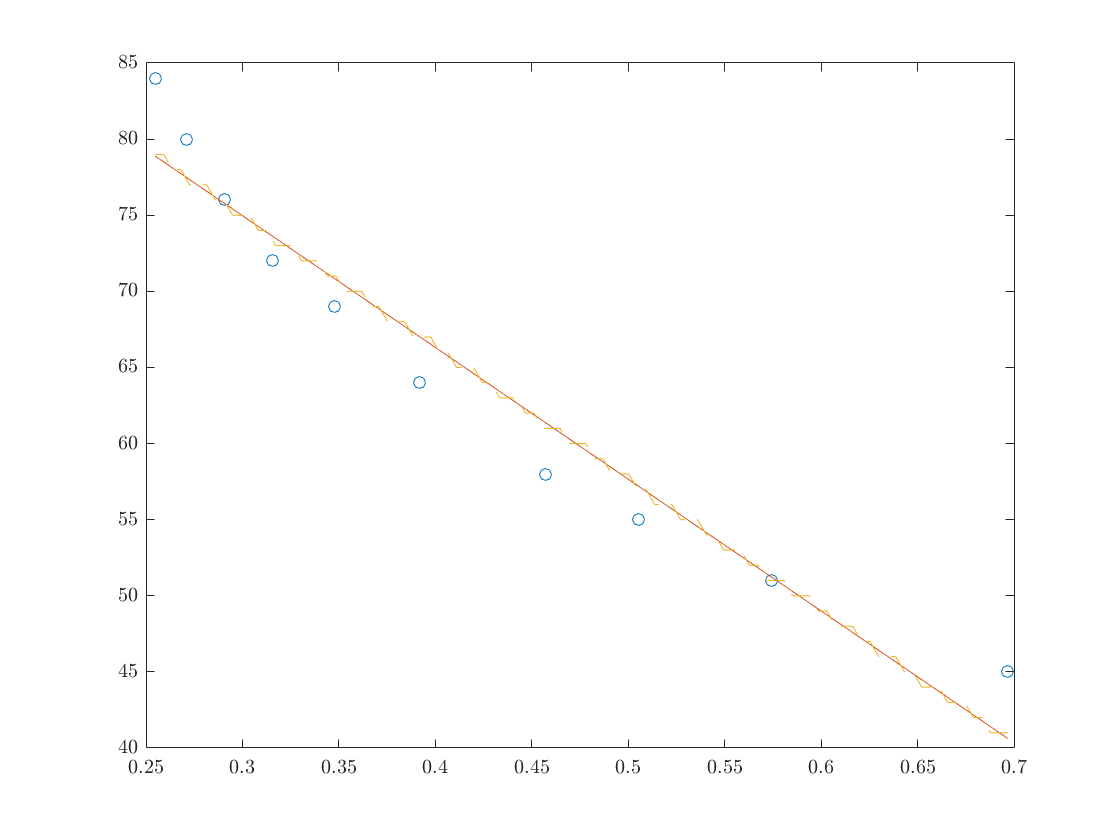

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

p = polyfit(H,res,1);
y1 = polyval(p,linspace(0.6968,0.2547,100));
figure
plot(H,res,'o')
hold on
plot(linspace(0.6968,0.2547,100),y1)
plot(linspace(0.6968,0.2547,100),round(y1),'--')
hold off

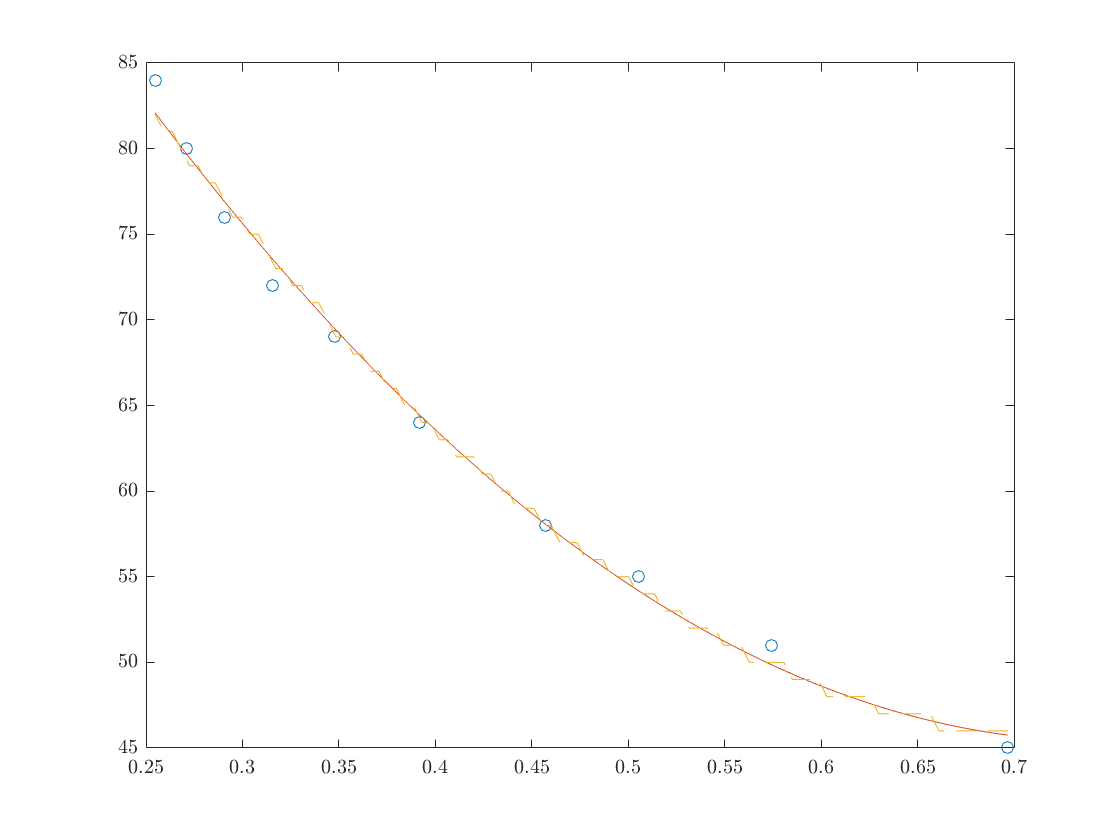


p = polyfit(H,res,2);
y1 = polyval(p,linspace(0.6968,0.2547,100));
figure
plot(H,res,'o')
hold on
plot(linspace(0.6968,0.2547,100),y1)
plot(linspace(0.6968,0.2547,100),round(y1),'--')
hold off

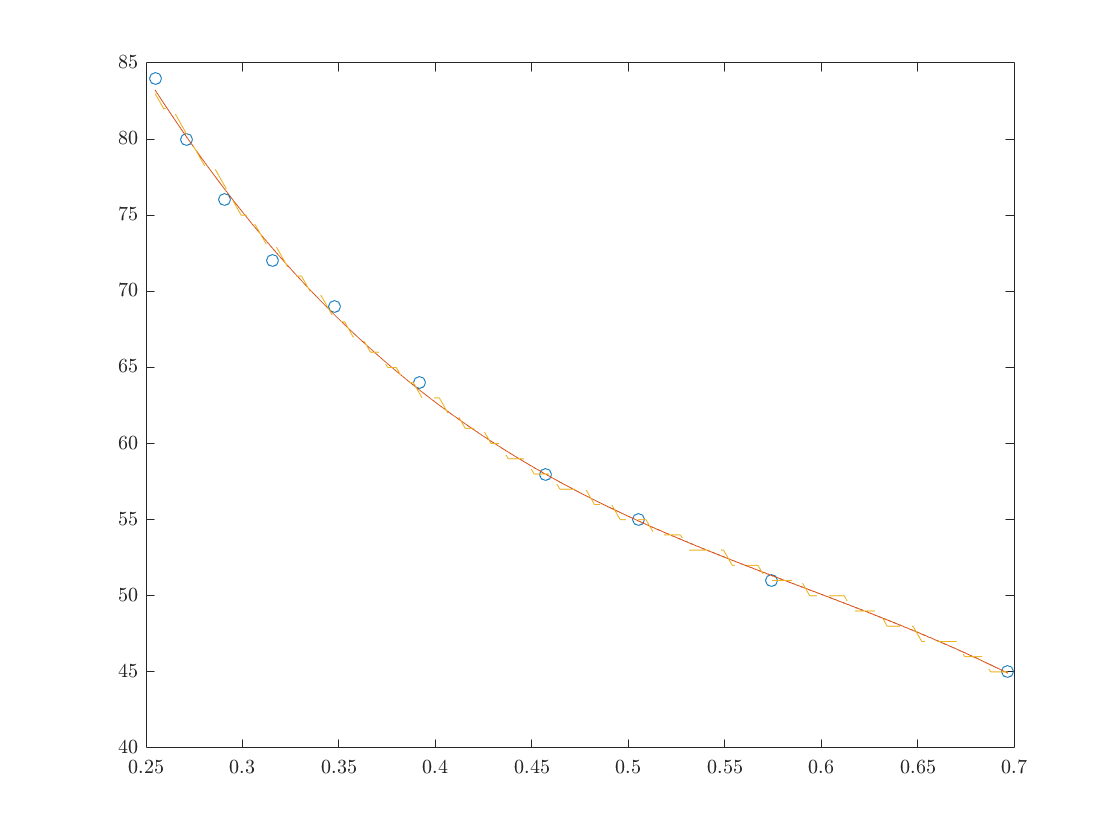


p = polyfit(H,res,3);
y1 = polyval(p,linspace(0.6968,0.2547,100));
figure
plot(H,res,'o')
hold on
plot(linspace(0.6968,0.2547,100),y1)
plot(linspace(0.6968,0.2547,100),round(y1),'--')
hold off


p = polyfit(H,res,4)

p = 	1.0e+03 *

    1.6312   -3.4829    2.8232   -1.0927    0.2295


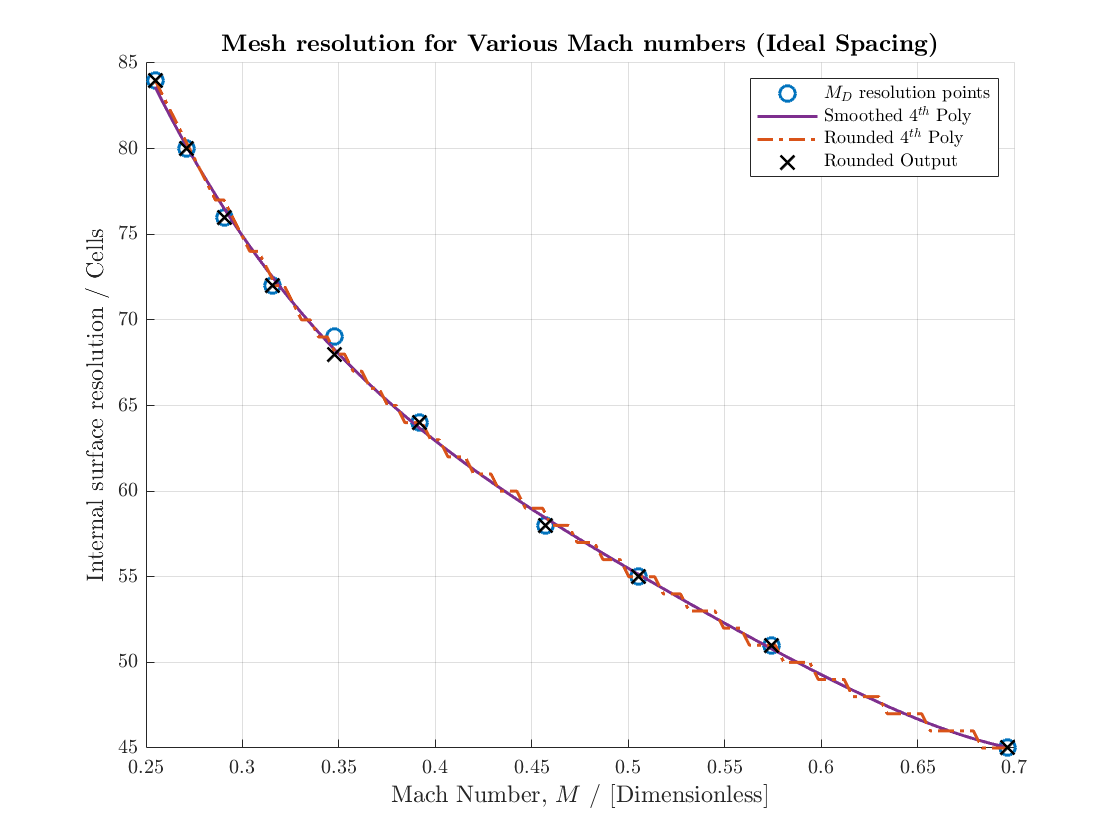

vals=p(1)*H.^4+p(2)*H.^3+p(3)*H.^2+p(4)*H+p(5);
y1 = polyval(p,linspace(0.6968,0.2547,100));
figure
plot(H,res,'o',"LineWidth",1.5,"MarkerSize",msize,"Color",blue)
hold on
plot(linspace(0.6968,0.2547,100),y1,'-',"LineWidth",1.5,"MarkerSize",msize,"Color",purple)
plot(linspace(0.6968,0.2547,100),round(y1),'-.',"LineWidth",1.5,"MarkerSize",msize,"Color",orange)
plot(H,round(vals),'x',"LineWidth",1.5,"MarkerSize",msize,"Color",black)
grid on; box off; hold on
title("\textbf{Mesh resolution for Various Mach numbers (Ideal Spacing)}",'FontSize',tsize)
xlabel("Mach Number, $M$ / [Dimensionless]",'FontSize',lsize)
ylabel("Internal surface resolution / Cells",'FontSize',lsize)
legend('$M_D$ resolution points','Smoothed $4^{th}$ Poly','Rounded $4^{th}$ Poly','Rounded Output','location','northeast','FontSize',legsize)

hold off


H=0.6968

H = 0.6968

x= round((1631.2*(H*H))-(3482.9*(H^3))+(2823.2*(H^2))-(1092.7*H)+229.5)

x = 453

H=0.2547

H = 0.2547

x= round((1631.2*(H^4))-(3482.9*(H^3))+(2823.2*(H^2))-(1092.7*H)+229.5)

x = 84

## Pressure curves

Ma = [1.5 1.7 2.2 3];
Amount_covered = [0.44 0.28 0.26 0.25]*0.5;

f=fit(transpose(Ma),transpose(Amount_covered),'exp2')

f =      General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients:
       a =   1.454e+07
       b =      -12.63
       c =      0.1447
       d =    -0.04892

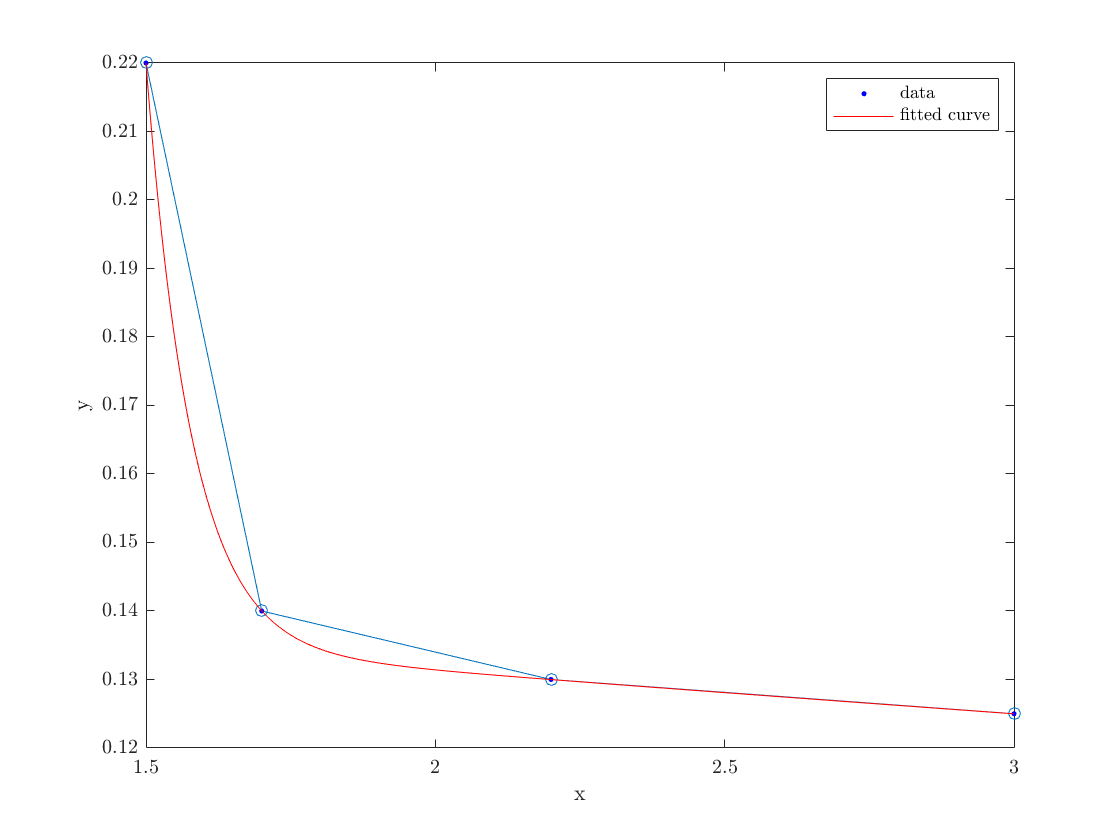

figure
plot(Ma,Amount_covered,'o-')
hold on
plot(f,transpose(Ma),transpose(Amount_covered))
hold off


startf = [0.92 1 1.08 1.13];
f=fit(transpose(Ma),transpose(startf),'exp2')

f =      General model Exp2:
     f(x) = a*exp(b*x) + c*exp(d*x)
     Coefficients:
       a =      0.9896
       b =     0.04441
       c =         -30
       d =      -3.589

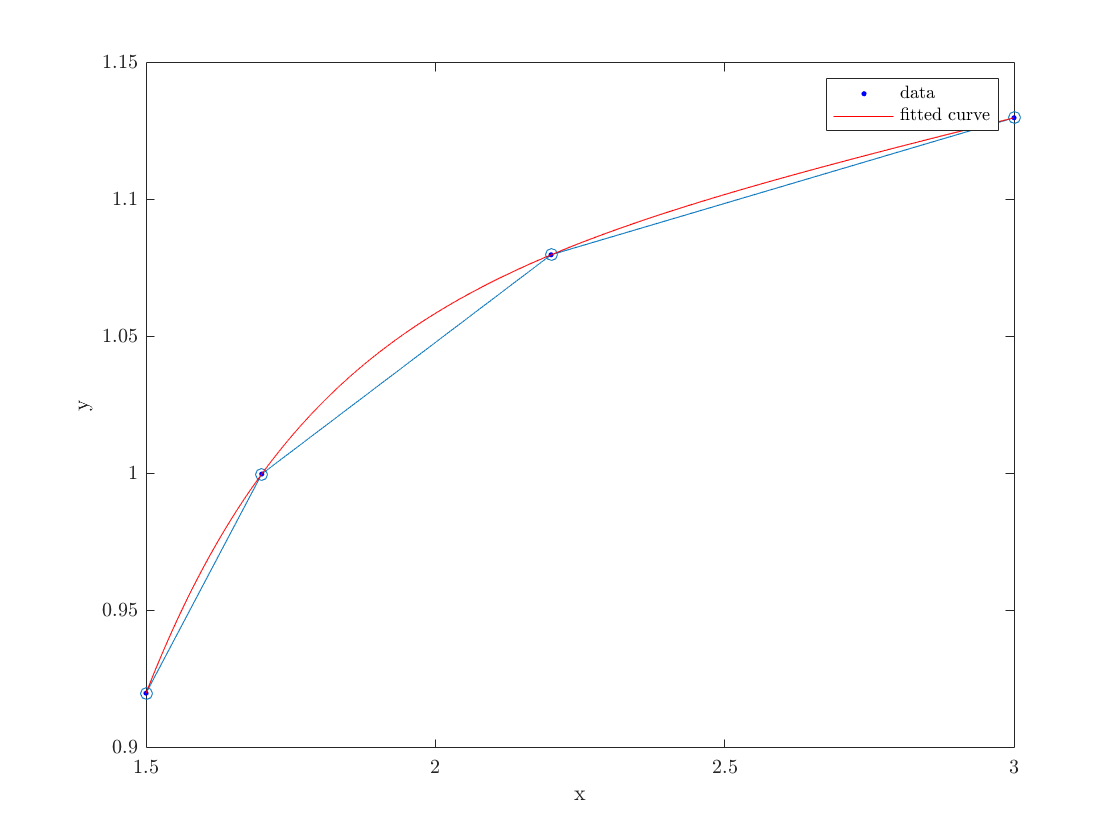

figure
plot(Ma,startf,'o-')
hold on
plot(f,transpose(Ma),transpose(startf))


endf = [0.92 0.925 0.94 1];
f=fit(transpose(Ma),transpose(endf),'poly3')

f =      Linear model Poly3:
     f(x) = p1*x^3 + p2*x^2 + p3*x + p4
     Coefficients:
       p1 =     0.01832
       p2 =    -0.09176
       p3 =      0.1778
       p4 =       0.798

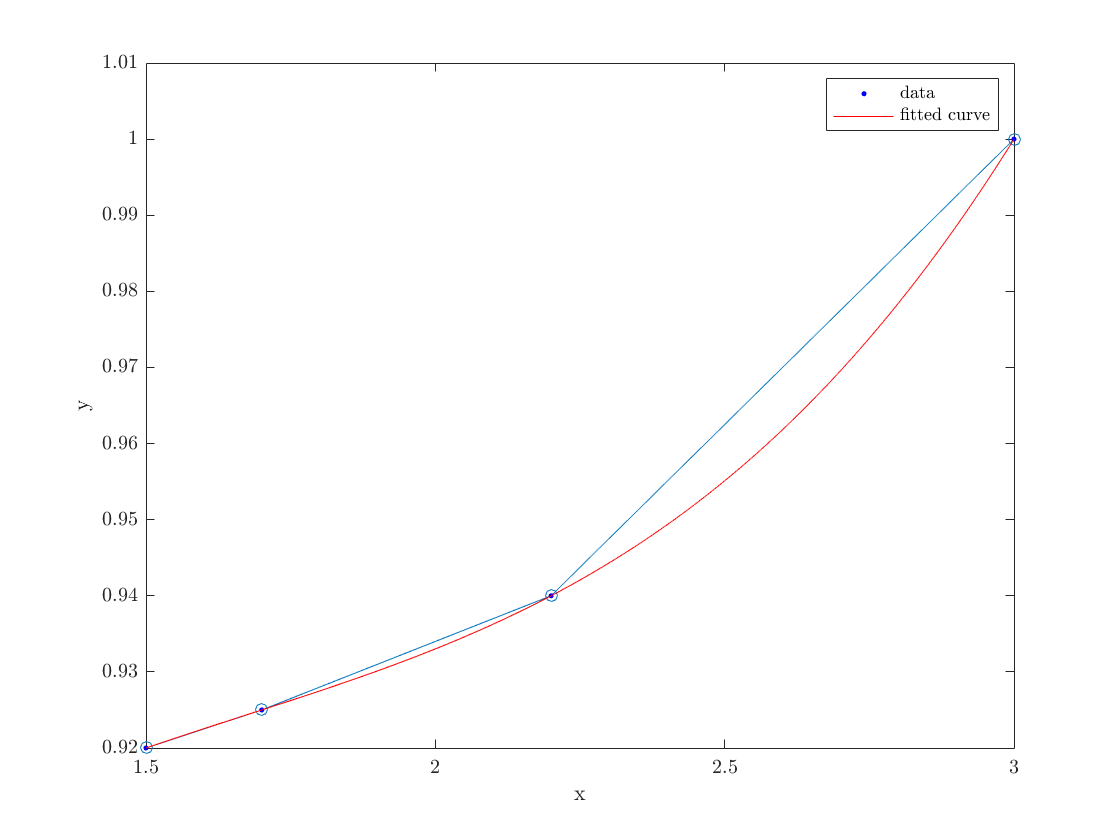

figure
plot(Ma,endf,'o-')
hold on
plot(f,transpose(Ma),transpose(endf))